# Design and Evaluation of a Digital Synthesiser Voice

### Abstract

### Introduction

This purpose of this __ is to analyse, evaluate and compare the harmonic content and aliasing effects of an FM synthesis and a subtractive synthesis.

### Method and Theory

clear; close all;

fs = 44100;                   % Sampling Frequency (Hz)
dur = 3;                      % Duration of Smaple (s)
f0 = 220;                     % Fundemental frequncy of signal (Hz)
fm = 4400;                    % Frequncy of the modulator signal (Hz)
modDepth = 20;                % Depth of the modulator signal (affects the amplitude)

t = (0 : round(fs * dur) - 1) / fs ;

#### Oscillator 

osc = sawtooth(2*pi*f0*t);         %creating a sine wave using the "sin" function, using the variables for fundemental frequency "f0" 
oscFm = sin(2 * pi * f0 * t + (modDepth * sin(2 * pi * fm * t)));


#### ASDR

env = adsr(fs, dur, 0.7 , 0.9 , 0.5 , 0.3); %function for ADSR envelope
oscEnv = osc .* env;

#### Filters

sig = lfosig(oscEnv, fs,  0.3 , 0.15 , 0.5);

#### Soft Clipping

gain = 1;
sigClip = tanh(gain * sig)/gain ;

#### Audio Output

sigout = sigClip/ max(abs(sigClip));

SawFilename = 'Sawtooth Before.wav';
audiowrite(SawFilename, osc, fs);

FMFilename = 'FM Before.wav';
audiowrite(FMFilename, oscFm, fs);

SawEndName = 'Sawtooth After';
audiowrite(SawEndName, sigout, fs);

#### Plots and Figures

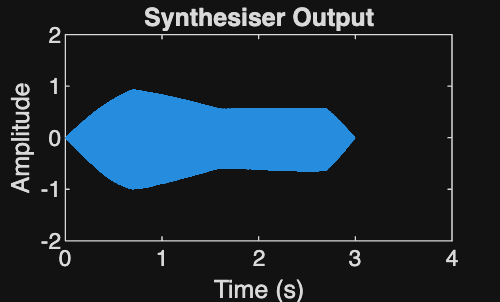

figure;
plot(t, sigout);
xlabel('Time (s)');  ylabel('Amplitude');
title('Synthesiser Output');

xlim([0.00 4.00])
ylim([-2.00 2.00])

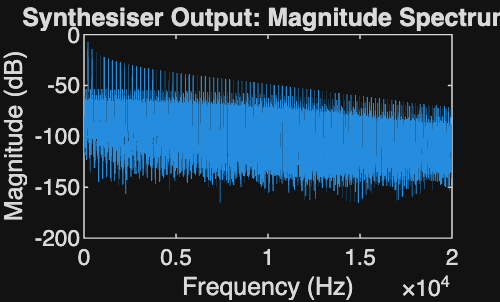


figure;
plot_spectrum(sigout, fs);
title('Synthesiser Output: Magnitude Spectrum');
xlim([0, 20000]);

#### Functions

function env = adsr(fs, dur, a, d, s, r)
    N = round(fs * dur);
    Na = round(fs * a);
    Nd = round(fs * d);
    Nr = round(fs * r);
    Ns = N - Nr;

    env = [linspace(0, 1, Na), linspace(1, s, Nd), s * ones(1, Ns - Na - Nd), linspace(s, 0, Nr)];
    env = env(1:N);
end

function sig = lfosig(oscEnv, fs, fcentre, depth, Flfo)
    block = 256;
    sig = zeros(size(oscEnv));
    zi = zeros(2, 1); % IIR filter state (2 states for biquad )
    
    for k = 1 : block : length(oscEnv) - block
        idx = k : k + block - 1;
        t_k = (k -1) / fs ; % time at block start

        % LFO and clamped cutoff
        fc = fcentre + (depth * sin(2* pi* Flfo * t_k));
        fC = max (0.01, min(0.99, fc));

        % Redesign and apply filter ( butter : Signal Processing Toolbox )
        [b, a] = butter(2, fC);
        [sig(idx),zi] = filter(b, a, oscEnv(idx), zi);
    end
end

function plot_spectrum(sigout, fs)

    N = length(sigout);
    spec_length = floor(N/2 + 1);

    dft = fft(sigout);
    spec = dft(1:spec_length);
    mag = abs(spec)/N;
    mag(2:ceil(N/2)) = 2*mag(2:ceil(N/2));
    mag = 20*log10(mag);

    k = 0:(spec_length - 1);
    freqs = k*fs/N;

    plot(freqs, mag);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
end